- Аналоговый сигнал

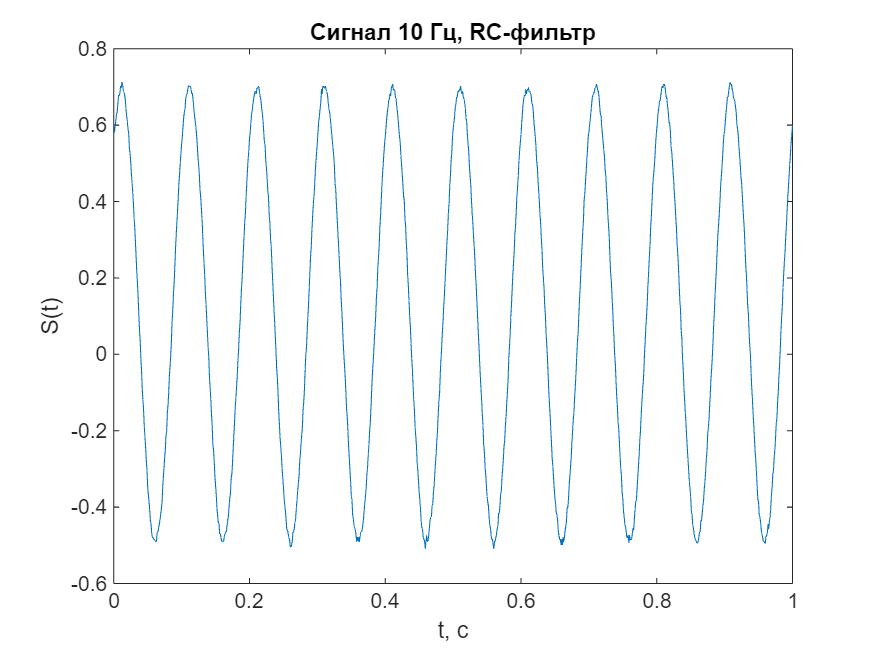

clear
S = readlines("C:\Users\cold1\Desktop\dsp 2\putty10hzANALOG.log");
noise = readlines("C:\Users\cold1\Desktop\dsp 2\putty100hzANALOG.log");
L = min(length(S), length(noise)) - 1;
S = S(2:L);
noise = noise(2:L);
S = str2double(S);
noise = str2double(noise);
S = S / (1024 / 5) - 1.5;
noise = noise / (1024 / 5) - 1.5;
Sn = S + noise;
Fs = 1000;
t = 1/Fs : 1/Fs : 10;
f = (0 : (length(Sn) - 1)) * Fs / length(Sn);
plot(t(1:1000),S(1:1000))
title("Сигнал 10 Гц, RC-фильтр")
xlabel("t, с")
ylabel("S(t)")

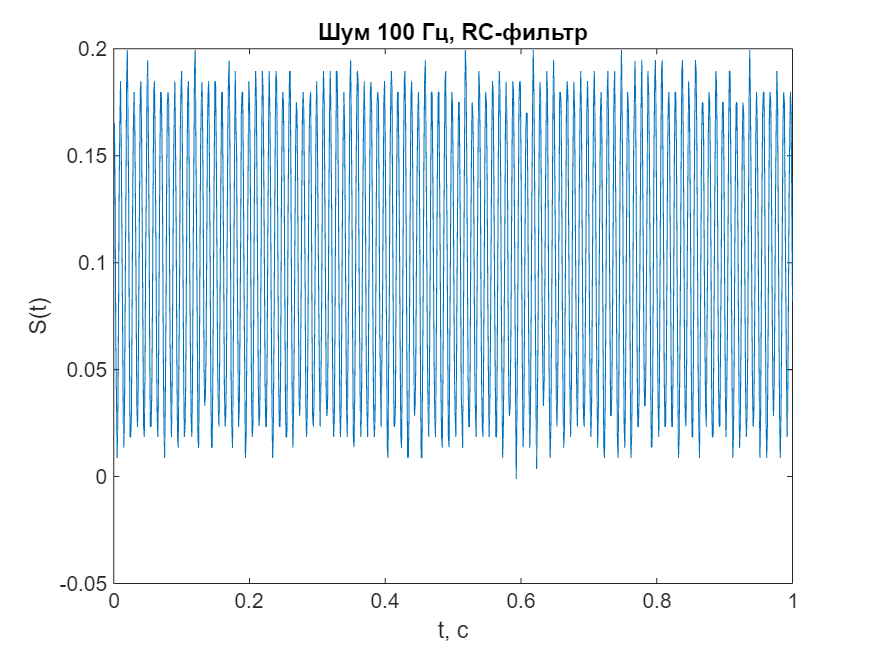

plot(t(1:1000),noise(1:1000))
title("Шум 100 Гц, RC-фильтр")
xlabel("t, с")
ylabel("S(t)")

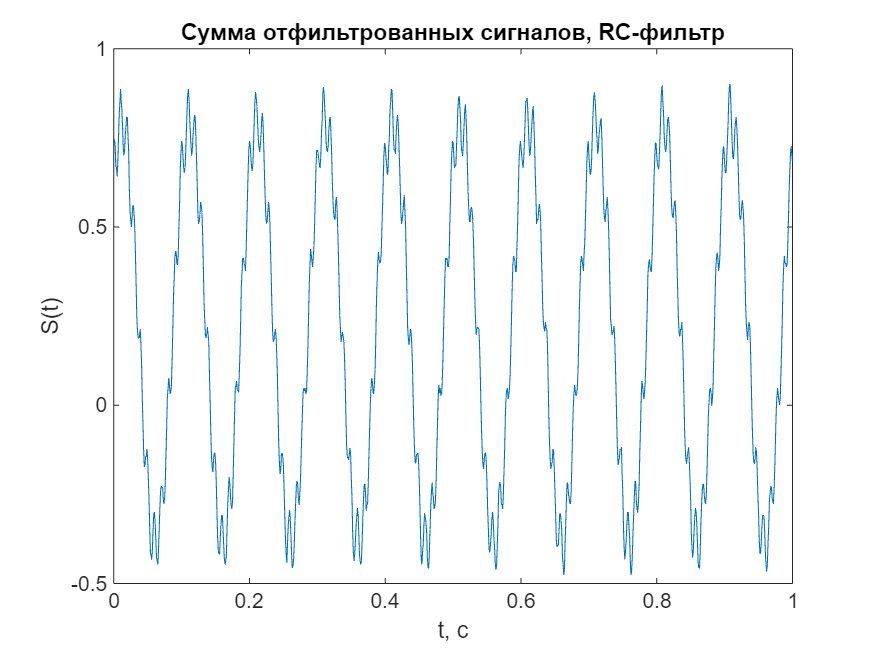

plot(t(1:1000),Sn(1:1000))
title("Сумма отфильтрованных сигналов, RC-фильтр")
xlabel("t, с")
ylabel("S(t)")

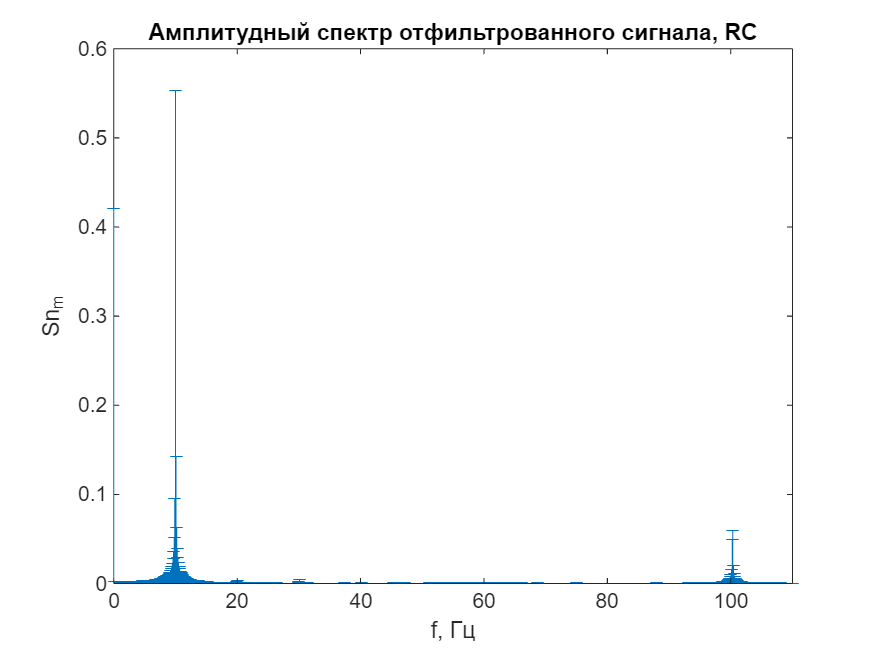

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.3; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала, RC")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

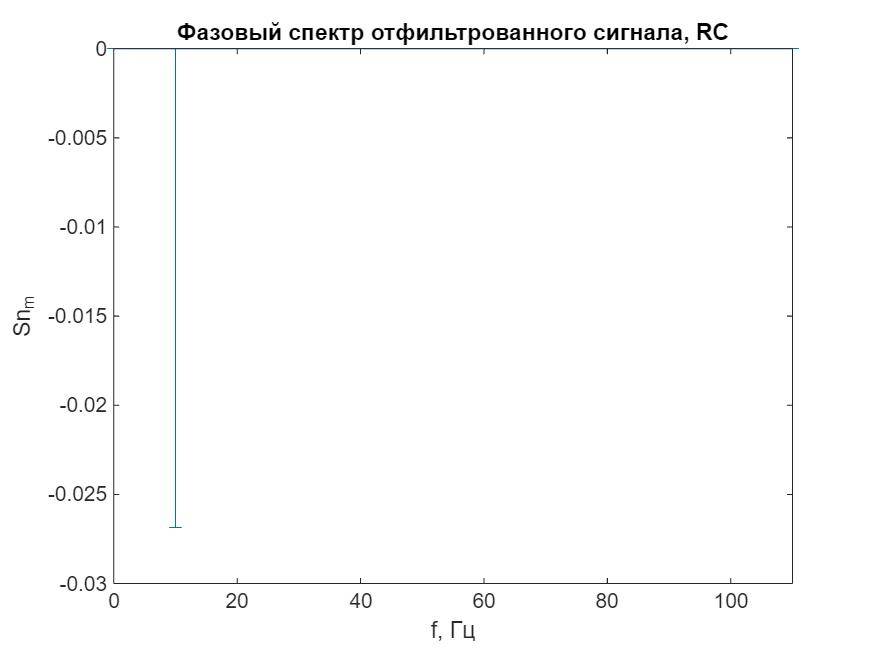

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала, RC")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

2. Неотфильтрованный сигнал

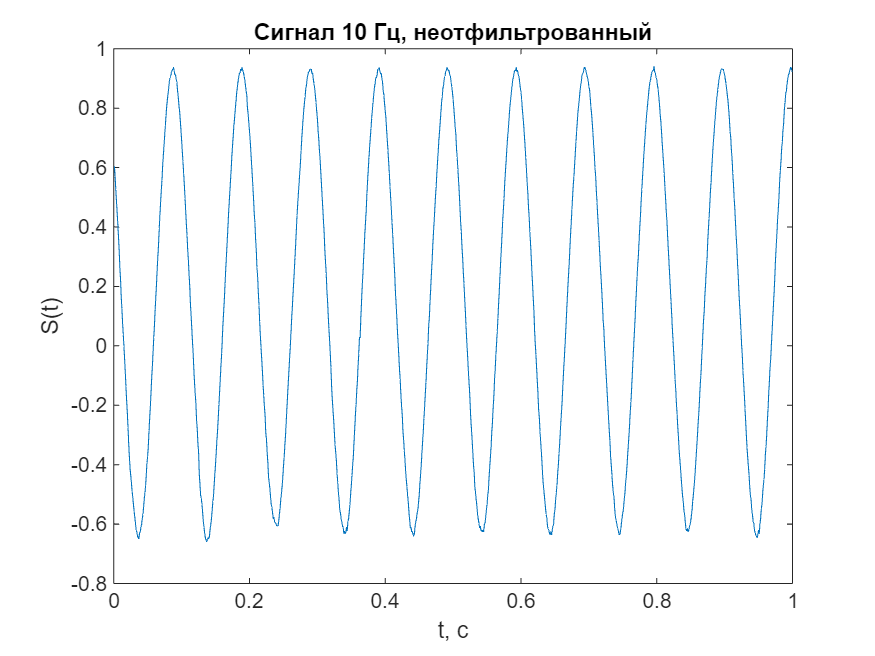

clear
S = readlines("C:\Users\cold1\Desktop\dsp 2\putty10hzClean.txt");
noise = readlines("C:\Users\cold1\Desktop\dsp 2\putty100hzClean.txt");
L = min(length(S), length(noise)) - 1;
S = S(2:L);
noise = noise(2:L);
S = str2double(S);
noise = str2double(noise);
S = S / (1024 / 5) - 1.5;
noise = noise / (1024 / 5) - 1.5;
Sn = S + noise;
Fs = 1000;
t = 1/Fs : 1/Fs : 10;
f = (0 : (length(Sn) - 1)) * Fs / length(Sn);
plot(t(1:1000),S(1:1000))
title("Сигнал 10 Гц, неотфильтрованный")
xlabel("t, с")
ylabel("S(t)")

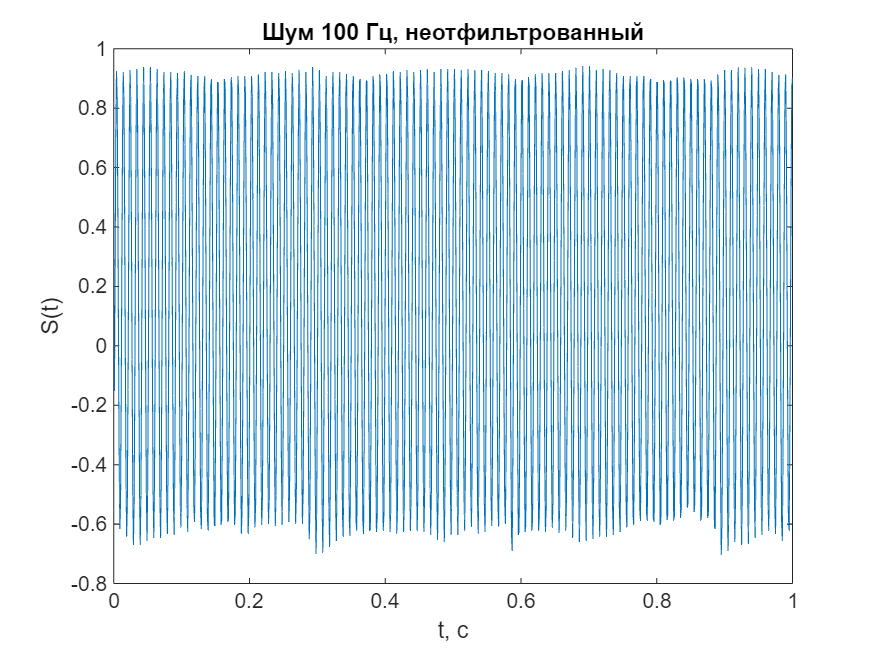

plot(t(1:1000),noise(1:1000))
title("Шум 100 Гц, неотфильтрованный")
xlabel("t, с")
ylabel("S(t)")

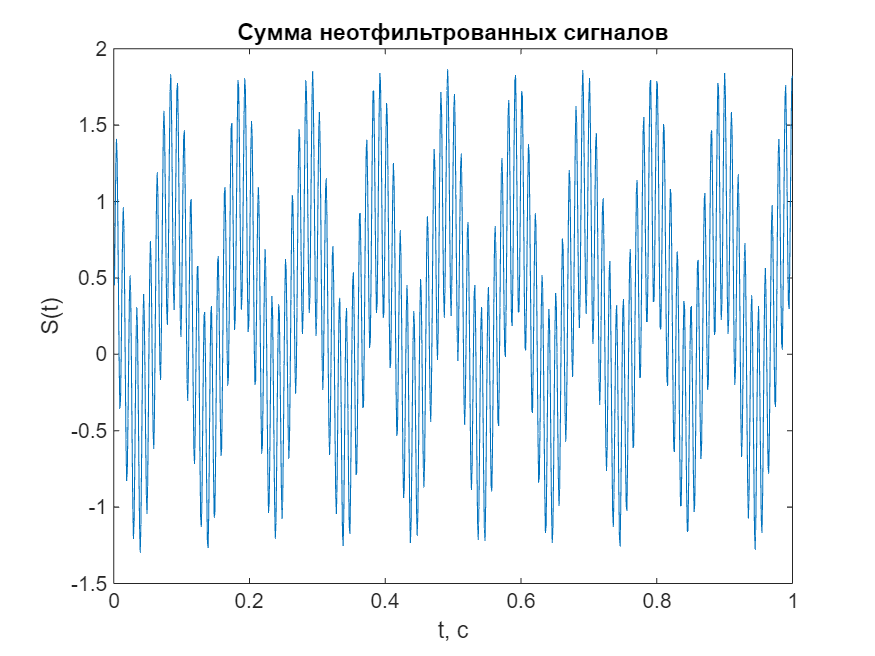

plot(t(1:1000),Sn(1:1000))
title("Сумма неотфильтрованных сигналов")
xlabel("t, с")
ylabel("S(t)")

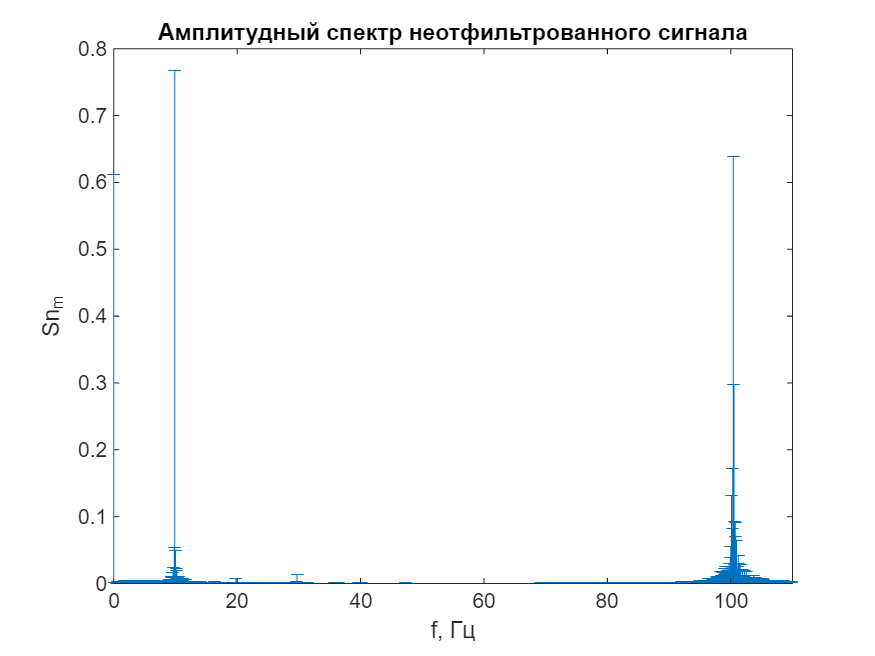

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.5; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр неотфильтрованного сигнала")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

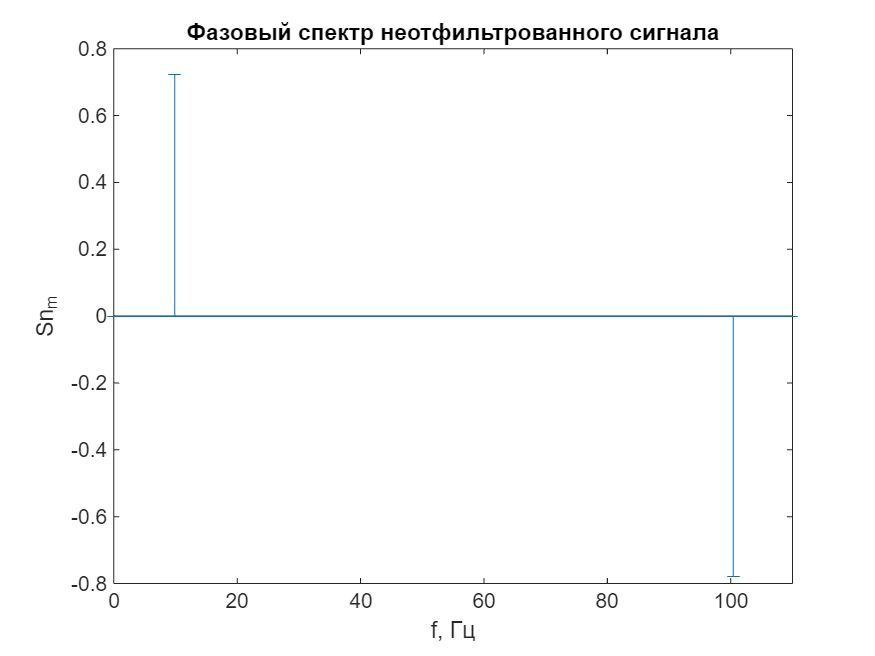

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр неотфильтрованного сигнала")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

3. КИХ-фильтр

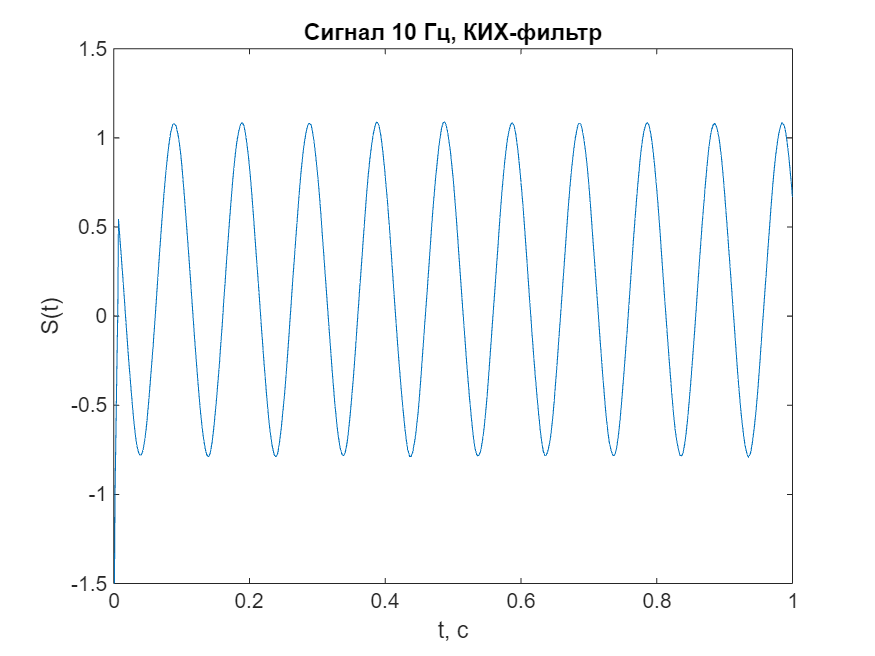

clear
S = readlines("C:\Users\cold1\Desktop\dsp 2\putty10hzFIR.log");
noise = readlines("C:\Users\cold1\Desktop\dsp 2\putty100hzFIR.log");
L = min(length(S), length(noise)) - 1;
S = S(2:L);
noise = noise(2:L);
S = str2double(S);
noise = str2double(noise);
S = S / (1024 / 5) - 1.5; 
noise = noise / (1024 / 5) - 1.5;
Sn = S + noise;
Fs = 1000;
t = 1/Fs : 1/Fs : 10;
f = (0 : (length(Sn) - 1)) * Fs / length(Sn);
plot(t(1:1000),S(1:1000))
title("Сигнал 10 Гц, КИХ-фильтр")
xlabel("t, с")
ylabel("S(t)")

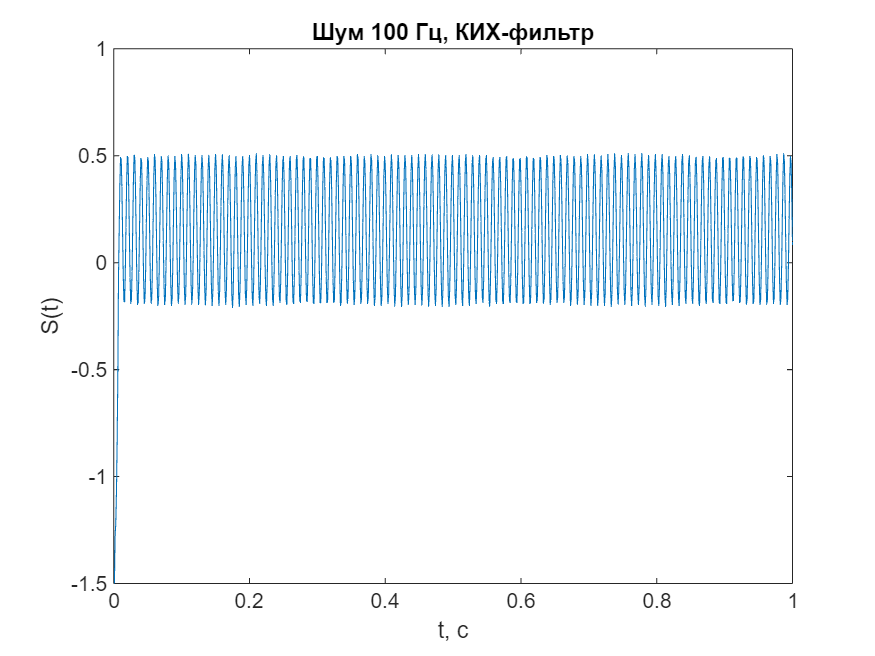

plot(t(1:1000),noise(1:1000))
title("Шум 100 Гц, КИХ-фильтр")
xlabel("t, с")
ylabel("S(t)")

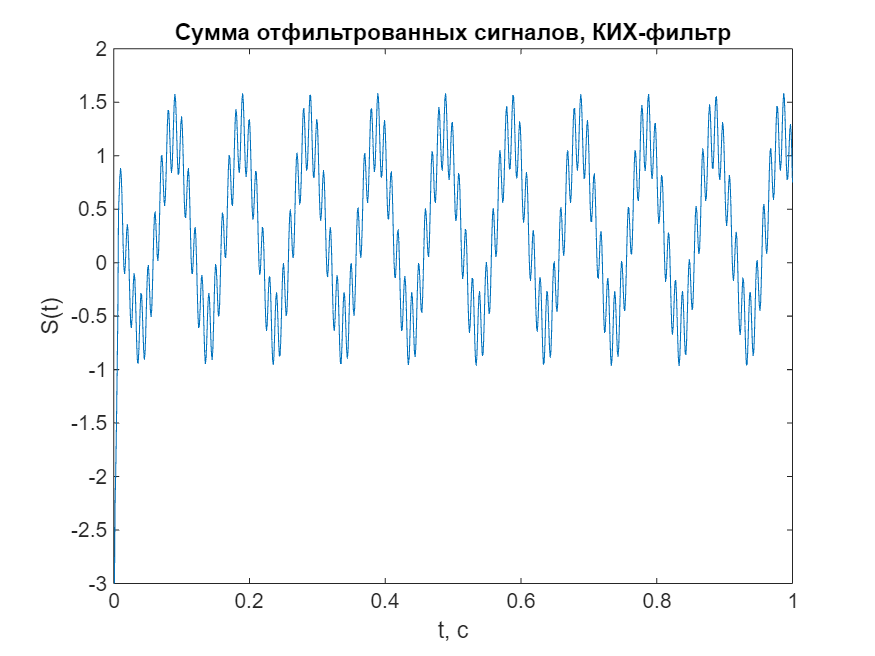

plot(t(1:1000),Sn(1:1000))
title("Сумма отфильтрованных сигналов, КИХ-фильтр")
xlabel("t, с")
ylabel("S(t)")

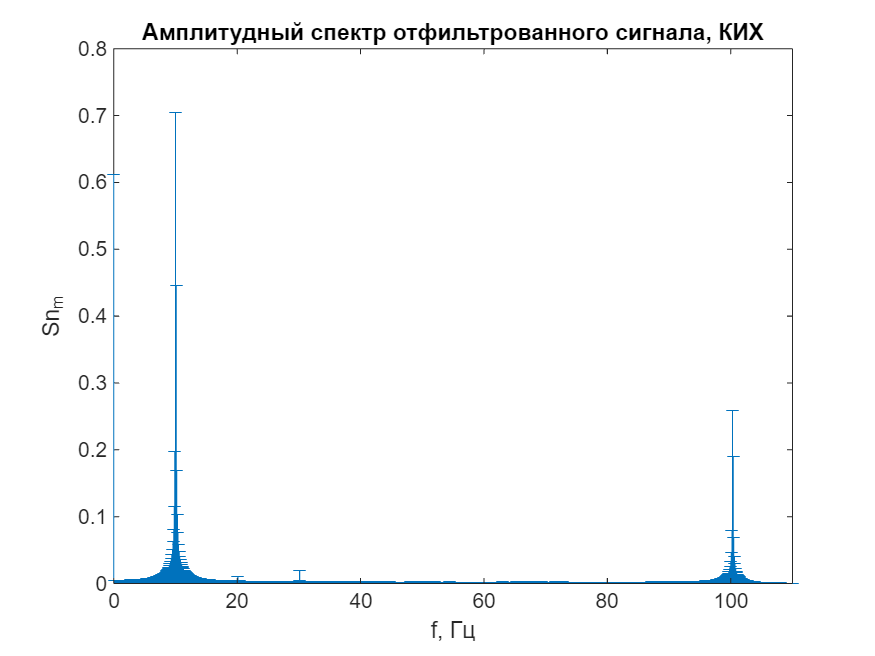

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.7; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала, КИХ")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

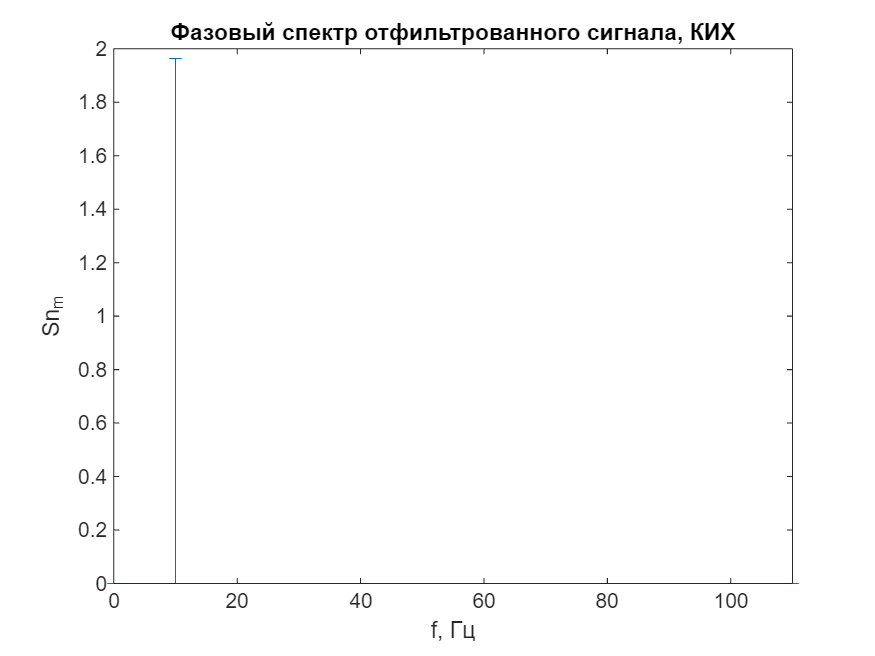

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала, КИХ")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

4. БИХ-фильтр

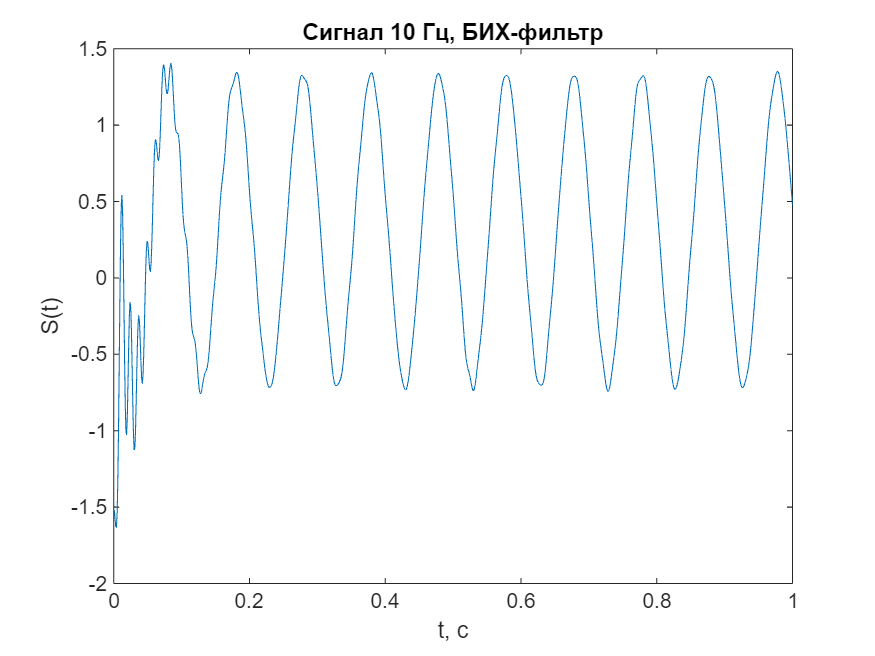

clear
S = readlines("C:\Users\cold1\Desktop\dsp 2\putty10hzIIR.log");
noise = readlines("C:\Users\cold1\Desktop\dsp 2\putty100hzIIR.log");
L = min(length(S), length(noise)) - 1;
S = S(2:L);
noise = noise(2:L);
S = str2double(S);
noise = str2double(noise);
S = S / (1024 / 5) - 1.5;
noise = noise / (1024 / 5) - 1.5;
Sn = S + noise;
Fs = 1000;
t = 1/Fs : 1/Fs : 10;
f = (0 : (length(Sn) - 1)) * Fs / length(Sn);
plot(t(1:1000),S(1:1000))
title("Сигнал 10 Гц, БИХ-фильтр")
xlabel("t, с")
ylabel("S(t)")

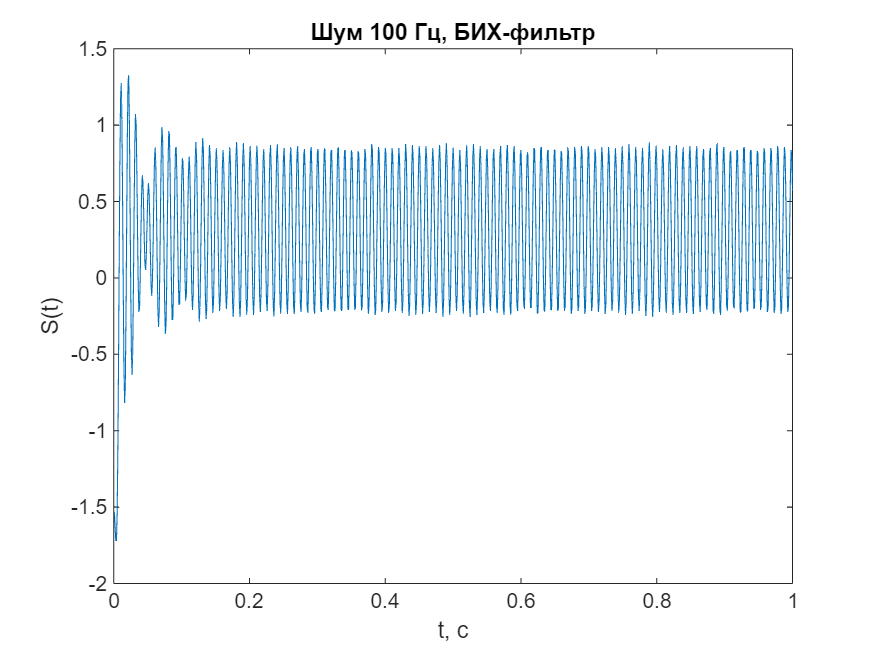

plot(t(1:1000),noise(1:1000))
title("Шум 100 Гц, БИХ-фильтр")
xlabel("t, с")
ylabel("S(t)")

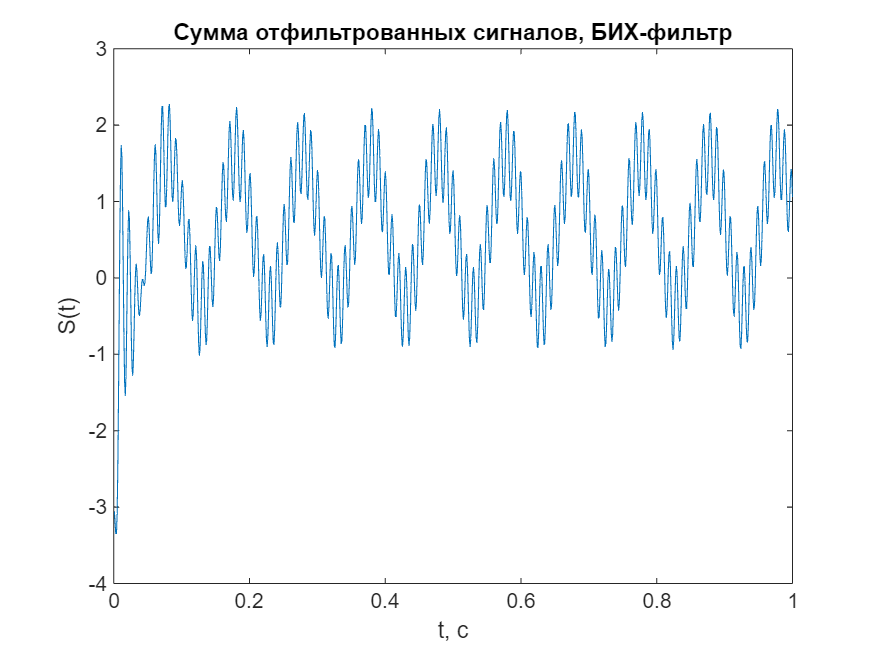

plot(t(1:1000),Sn(1:1000))
title("Сумма отфильтрованных сигналов, БИХ-фильтр")
xlabel("t, с")
ylabel("S(t)")

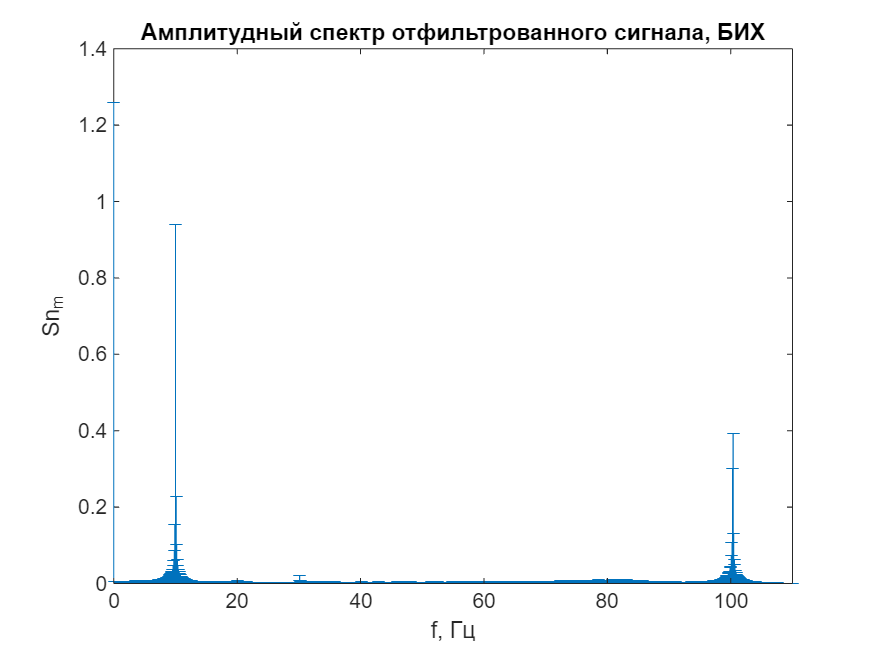

Sn_FFT = fft(Sn);
ampl = abs(Sn_FFT) / length(Sn_FFT) * 2;
crit = max(ampl(2:length(ampl) - 1));
mult = 0.35; % 250-2000 0.15, 10k 0.3, 20k 0.6
ampl_exc = zeros(1, length(ampl));
ampl_exc(ampl > crit * mult) = ampl(ampl > crit * mult);
phase = angle(Sn_FFT);
phase_exc = zeros(1, length(phase));
phase_exc(ampl > crit * mult) = phase(ampl > crit * mult);
stem(f(1 : round(length(f)/2)), ampl(1 : round(length(f)/2)), "Marker","_")
title("Амплитудный спектр отфильтрованного сигнала, БИХ")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])

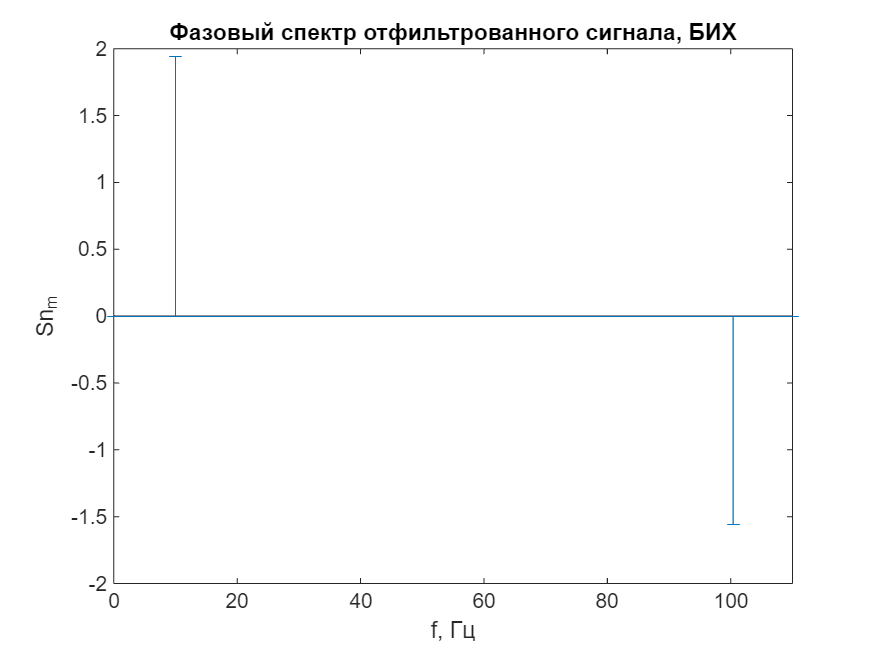

stem(f(1 : round(length(f)/2)), phase_exc(1 : round(length(f)/2)), "Marker","_")
title("Фазовый спектр отфильтрованного сигнала, БИХ")
ylabel("Sn_m")
xlabel("f, Гц")
xlim([0,110])